# Analysis of the connection of two pipes

close all;
clear all;
clc;

%including all parent folders up to the file 'code', this makes visible all
%files within this code
addingPathParentFolderByName('COMSOL_3_pipes_w_100um_rectangular_tetrazine');

Adding matlab path to: D:\code\NN_molecular_communications\Section_IV_BioComputing\COMSOL_3_pipes_w_100um_rectangular_tetrazine


#### Parameters

%call to the parameters file
Parameters

p0 = 600

mu = 9.9792e-04

D_coeff = 4.9000e-10

#### Flow rate for a given pressure drop  

**Description:** This block assumes a syringe is connected to the inlet of the pipe and introduces a constant flow rate Q. The pressure formula follows the Hagen–Poiseuille equation [1, Eq. (3.1) and Table 3.1 pp. 43]

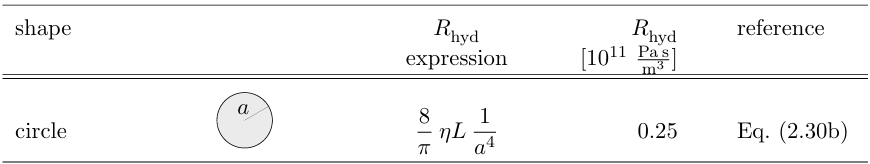

$\Delta P=RQ
$, (1)

where $R$ denotes the pipe resistance and is given as follows

- Rectangular cross-shape $R=\frac{12\mu L}{1-0.63\frac{h}{w}}\cdot\frac{1}{h^3w}$, $w\gg h$

- Circular cross-shape $R=\frac{8\mu L}{\pi r^4}$

where 

$\mu$ is the water viscosity,

$L$ is the channel length,

$r$ is the radius of a circular pipe.

$h$ is the height of a rectangular pipe

$w$ is the width of a rectangular pipe

### Flow

% %flow rate in [uL/min], achievable in 0.5-7 ul/min as in [4]
% Q_uL_m=2
% %flow rate in [m^3/s]
% Q_m3_s=Q_uL_m*(1e-6*1e-3)/60;

% Q_nL_per_min=10;
% Q=Q_nL_per_min*10^(-9)*10^(-3)/60;
% Delta_P=(8*mu_Water*L_outer)/(pi*radius_cylinder_1^4)*Q
% Delta_P_mmHg=Delta_P/133.322
%flow rate in [m^3/s]
% Q_m3_s=p0*(pi*r_vec.^4)/(8*mu*l_vec(end));
% %flow rate in [uL/min]
% Q_uL_m=Q_m3_s*60/(1e-6*1e-3);
% disp(['Min Q_ul_m=',num2str(min(Q_uL_m))])
% disp(['Max Q_ul_m=',num2str(max(Q_uL_m))])
% 
% %flow rate in [uL/h]
% Q_uL_h=Q_m3_s*60*60/(1e-6*1e-3);

% %Evaluating the reader volume and time to fill the volume
% r_Reader=500e-6/2;
% r_pipe=max(r_vec);
% delta_t_min=2*pi*r_Reader^2*r_pipe/max(Q_m3_s)
% delta_t_max=2*pi*r_Reader^2*r_pipe/min(Q_m3_s)


#### Length and width per pipe

%Pipe_1
%width
w_1=0;
[var,factor]=getVarTable(w_1,table);
w_1=eval(var{1})*factor

w_1 = 1.1273e-04

%heigth
height_pipe=0;
[var,factor]=getVarTable(height_pipe,table);
height_pipe=eval(var{1})*factor

height_pipe = 5.0000e-05

%Length
L_1=0;
[var,factor]=getVarTable(L_1,table);
L_1=eval(var{1})*factor

L_1 = 0.0210


%Pipe_2
%width
w_2=0;
[var,factor]=getVarTable(w_2,table);
w_2=eval(var{1})*factor

w_2 = 1.3474e-04

%Length
L_2=0;
[var,factor]=getVarTable(L_2,table);
L_2=eval(var{1})*factor

L_2 = 0.0311

%Angle
varphi_2=0;
[var,factor]=getVarTable(varphi_2,table);
varphi_2=eval(var{1})*factor

varphi_2 = 1.6566


%Pipe_3
%width
w_3=0;
[var,factor]=getVarTable(w_3,table);
w_3=eval(var{1})*factor

w_3 = 1.4314e-04

%Length
L_3=0;
[var,factor]=getVarTable(L_3,table);
L_3=eval(var{1})*factor

L_3 = 0.0383

%Angle
varphi_3=0;
[var,factor]=getVarTable(varphi_3,table);
varphi_3=eval(var{1})*factor

varphi_3 = 1.9825


%resistance of the rectangular Pipe 1
R_1=12*mu_Water*L_1/(1-0.63*height_pipe/w_1)*(1/(height_pipe^3*w_1))

R_1 = 2.4768e+13

%resistance of the rectangular Pipe 2
R_2=12*mu_Water*L_2/(1-0.63*height_pipe/w_2)*(1/(height_pipe^3*w_2))

R_2 = 2.8822e+13

%resistance of the rectangular Pipe 3
R_3=12*mu_Water*L_3/(1-0.63*height_pipe/w_3)*(1/(height_pipe^3*w_3))

R_3 = 3.2905e+13


%evaluating the extra hydraulic resistance
% Specify the MAT file for the parameters
% csvFileName = 'COMSOL_pipe_1_concentration_line_outlet.csv';
csvFileName = 'polygon_outer.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
table=readtable(csvFileName,opts);
x_pol_outer=table.Var1;
y_pol_outer=table.Var2;

%evaluating the extra hydraulic resistance
% Specify the MAT file for the parameters
% csvFileName = 'COMSOL_pipe_1_concentration_line_outlet.csv';
csvFileName = 'polygon_upper.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
table=readtable(csvFileName,opts);
x_pol_upper=table.Var1;
y_pol_upper=table.Var2;

%length of the inlet
L_in=x_pol_outer(2)-x_pol_outer(1) %inlet connection to Pipes 2 and 3

L_in = 2.1000e-04

w_in=2*abs(y_pol_upper(1)-y_pol_outer(10))

w_in = 3.1072e-04


%length of the outlet
L_out=x_pol_outer(5)-x_pol_outer(4)

L_out = 2.1000e-04

w_out=abs(y_pol_outer(6)-y_pol_outer(5))

w_out = 9.8995e-05


%inlet resistance to Pipes 2 and 3
R_in=12*mu_Water*L_in/(1-0.63*height_pipe/w_in)*(1/(height_pipe^3*w_in))

R_in = 7.2052e+10

%outlet resistance
R_out=12*mu_Water*L_out/(1-0.63*height_pipe/w_out)*(1/(height_pipe^3*w_out))

R_out = 2.9807e+11


% Equivalent parallel resistance
Req = 1 / sum(1 ./ [R_1 R_2 R_3])

Req = 9.4822e+12


%Flow to the pipe 1 in a single connection
Q_1=p0/(Req)*Req/R_1;
Q_1_uL_min=Q_1*6e10

Q_1_uL_min = 1.4535



%Flow to the pipe 2 in a single connection
Q_2=p0/(R_in+R_out+Req)*Req/R_2;
Q_2_uL_min=Q_2*6e10

Q_2_uL_min = 1.2021



%Flow to the pipe 2 in a single connection
Q_3=p0/(R_in+R_out+Req)*Req/R_3;
Q_3_uL_min=Q_3*6e10

Q_3_uL_min = 1.0530

#### Péclet condition

Pe_cond=zeros(length(w_vec),length(l_vec));

Q_min=inf;
Q_max=-inf;

for i_w=1:length(w_vec)

    %i_r/length(r_vec)*100

    for i_l=1:length(l_vec)

        %Hydraulic Resistance
        R=12*mu*l_vec(i_l)/(1-0.63*height_pipe/w_vec(i_w))*1/(height_pipe^3*w_vec(i_w));
        
        %Volumetric flow
        Q=p0/R;

        %Mean velocity
        %Circular channel of radius r_vec(i_r) [2, pag. 54]
        % v_char=r_vec(i_r)^2*p0/(3*mu*l_vec(i_l))
        %Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
        v_char=Q/(w_vec(i_w)*height_pipe);

        %Peclet number, see [3, Eq. below 11] 
        Pe=v_char*height_pipe/D_coeff;

        %Evaluating the Effective Diffusion coefficient
        %Circular channel: [1, Eq.(4.54) pp.77]
        %D_eff=r_vec(i_w)^2*v_char^2/48/D_coeff;
        %Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
        %Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
        D_eff=D_coeff*(1+1/200*Pe^2);

        % %Péclet number, circular channel this evaluation follows [1,Eq. (4.44) pp.75]
        % Pe=r_vec(i_r)*v_char/D_coeff;
        
        %Validating the diffusion within the pipe
        %Diffusion occurred along the radial axis and x-axis
        if(Pe<4*l_vec(i_l)/height_pipe && Pe>1)
            Pe_cond(i_w,i_l)=1;

            if(Q<Q_min)
                Q_min=Q;
                Q_min_w_idx=i_w;
                Q_min_l_idx=i_l;
            end

            if(Q>Q_max)
                Q_max=Q;
                Q_max_w_idx=i_w;
                Q_max_l_idx=i_l;
            end

        %Diffusion hasn't occurred along the radial axis and x-axis
        elseif(Pe>4*l_vec(i_l)/height_pipe)
            Pe_cond(i_w,i_l)=0;
        
        %Diffusion hasn't occurred along the axis
        elseif (Pe<1)
            Pe_cond(i_w,i_l)=-1;
        end
    end
end

disp(['Q_min=',num2str(Q_min*6e10),' uL/min'])

Q_min=0.85804 uL/min


disp(['Q_max=',num2str(Q_max*6e10),' uL/min'])

Q_max=5.442 uL/min


## Plotting the Pe_cond matrix

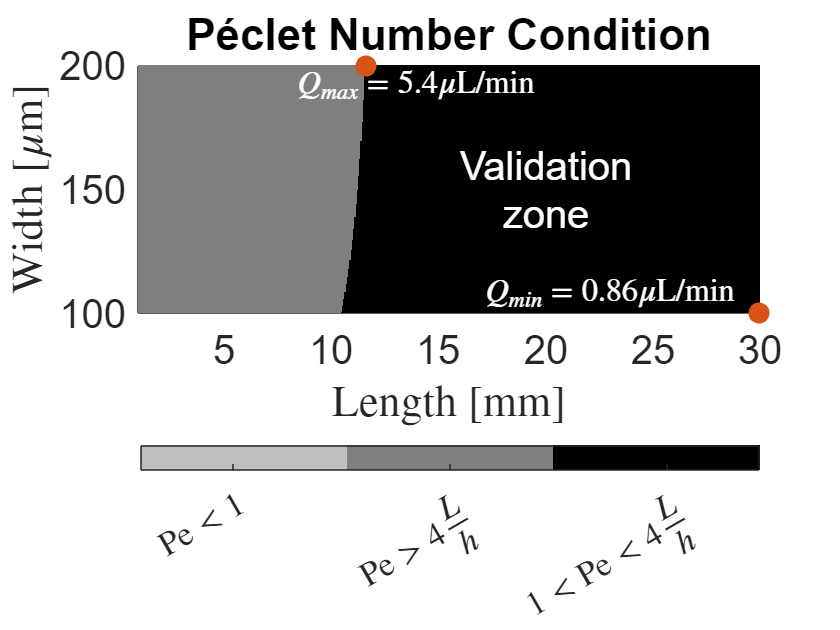

figure;

% Plot for all conditions in a single plot
hold on;
imagesc(l_vec*1e3, w_vec*1e6, Pe_cond); hold on
% colormap([0.8500 0.3250 0.0980; 0.9290 0.6940 0.1250; 0.0072 0.4470 0.7410]); % Colors for 0, -1, and 1
colormap([0.75, 0.75, 0.75; 0.5, 0.5, 0.5; 0, 0, 0]); % Colors for 0, -1, and 1
caxis([-1 1]); % Set color axis limits to match Pe_cond values

text(20,150,{'Validation', 'zone'},'FontSize',fontsize,'Color','w','HorizontalAlignment','center');

text(l_vec(Q_min_l_idx-120)*1e3,w_vec(Q_min_w_idx+40)*1e6,{strcat('$Q_{min}=',num2str(Q_min*6e10,2),' \mu$L/min')},'FontSize',fontsize-4,'Color','w','HorizontalAlignment','center',Interpreter='latex');
text(l_vec(Q_max_l_idx+40)*1e3,w_vec(Q_max_w_idx-40)*1e6,{strcat('$Q_{max}=',num2str(Q_max*6e10,2),' \mu$L/min')},'FontSize',fontsize-4,'Color','w','HorizontalAlignment','center',Interpreter='latex');

plot(l_vec(Q_min_l_idx)*1e3, w_vec(Q_min_w_idx)*1e6,'o','Color',"#D95319",MarkerFaceColor="#D95319",MarkerSize=10);
plot(l_vec(Q_max_l_idx)*1e3, w_vec(Q_max_w_idx)*1e6,'o','Color',"#D95319",MarkerFaceColor="#D95319",MarkerSize=10);


% Create a colorbar and set its ticks and labels
cb = colorbar('Ticks', [-0.7, 0, 0.7], 'TickLabels', {'$\mathrm{Pe}<1$', '$\mathrm{Pe}>4\frac{L}{h}$', '$1<\mathrm{Pe}<4\frac{L}{h}$'}, 'TickLabelInterpreter', 'latex', 'FontSize', fontsize-3,'Location','southoutside');
% cb.Layout.Tile='south';

% Set the color of the colorbar with transparency
%set(colorbarHandle, 'alpha', 0.5); % RGBA format, where A is the alpha value
%alpha(0.5);

xlabel('Length [mm]','Interpreter','latex');
ylabel('Width [$\mu$m]','Interpreter','latex');
axis([l_vec(1)*1e3 l_vec(end)*1e3 w_vec(1)*1e6 w_vec(end)*1e6])
set(gca, 'YDir', 'normal');
title('Péclet Number Condition');
set(gca,'FontSize',fontsize ,'YDir', 'normal'); % To display the y-axis in the correct direction
hold off;

### Peak time and peak amplitude vs width and length

% Q_min=inf;
% Q_max=-inf;
% 
% syms t
% 
% %length of the pipe
% total_points=1e2;
% w_vec=linspace(100e-6,200e-6,total_points);%selected based on the mixer dimenssion in [4, Fig. 3]
% l_vec=linspace(12,30,total_points)*1e-3;%selected based on the Peclet number condition
% 
% %defining the time interval
% total_points_time=1e2;
% t_ini=1e-7;
% t_end=10;
% t_vector = linspace(t_ini,t_end,total_points_time);
% time_sampling=t_vector(2)-t_vector(1);
% 
% h_amp=zeros(length(w_vec),length(l_vec));
% h_tau=zeros(length(w_vec),length(l_vec));
% 
% for i_w=1:length(w_vec)
% 
%     i_w/length(w_vec)*100
% 
%     for i_l=1:length(l_vec)
% 
%         %Hydraulic Resistance
%         R=12*mu*l_vec(i_l)/(1-0.63*height_pipe/w_vec(i_w))*1/(height_pipe^3*w_vec(i_w));
% 
%         %Volumetric flow
%         Q=p0/5/R;
% 
%         %Mean velocity
%         %Circular channel of radius r_vec(i_r) [2, pag. 54]
%         % v_char=r_vec(i_r)^2*p0/(3*mu*l_vec(i_l))
%         %Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
%         v_char=Q/(w_vec(i_w)*height_pipe);
% 
%         %Peclet number, see [3, Eq. below 11] 
%         Pe=v_char*height_pipe/D_coeff;
% 
%         %Evaluating the Effective Diffusion coefficient
%         %Circular channel: [1, Eq.(4.54) pp.77]
%         %D_eff=r_vec(i_w)^2*v_char^2/48/D_coeff;
%         %Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
%         %Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
%         D_eff=D_coeff*(1+1/200*Pe^2);      
% 
%         %Validating the diffusion within the pipe
%         %Diffusion occurred along the radial axis and x-axis
%         if(Pe<4*l_vec(i_l)/height_pipe && Pe>1)
%             %Evaluating the concentration of the straigth channel
%             c=1./2.*erfc((l_vec(i_l)-v_char*t)./(2*sqrt(D_eff*t)));
%             %Evaluating the channel impulse response
%             h=diff(c,t);
%             %for validation purposes only
%             % figure;
%             % figure;plot(t_vector,subs(h,t_vector)); grid on;
%             h_vs_t=subs(h,t_vector);
%             [h_amp(i_w,i_l),idx]=max(h_vs_t);
%             h_tau(i_w,i_l)=t_vector(idx);
%             %Fiding the peak of the channel ımpulse response
% 
%             if(Q<Q_min)
%                 Q_min=Q;
%                 Q_min_w_idx=i_w;
%                 Q_min_l_idx=i_l;
%             end
% 
%             if(Q>Q_max)
%                 Q_max=Q;
%                 Q_max_w_idx=i_w;
%                 Q_max_l_idx=i_l;
%             end
% 
%         %Diffusion hasn't occurred along the radial axis and x-axis
%         elseif(Pe>4*l_vec(i_l)/height_pipe)
%             disp(['Concentration is not constant along the x-axis, Pe=',num2str(double(Pe)),' is larger than ',num2str(4*l_vec(i_l)/height_pipe)])
%             i_l
%             i_r
% 
% 
%         %Diffusion hasn't occurred along the axis
%         elseif (Pe<1)
%             disp(['Diffusion hasn''t occurred along the axis, Pe=',num2str(double(Pe)),' is less than ',num2str(sqrt(48))])
%             i_l
%             i_r
% 
%         end
%     end
% end

ans = 1

ans = 2

ans = 3

ans = 4

ans = 5

ans = 6

ans = 7.0000

ans = 8

ans = 9

ans = 10

ans = 11

ans = 12

ans = 13

ans = 14.0000

ans = 15

#### Phase 1

%Pipe 1
% Specify the MAT file for the parameters
% csvFileName = 'COMSOL_pipe_1_concentration_line_outlet.csv';
csvFileName = '3D_Pipe_1_Outlet_Concentration_Surface_Average.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
table=readtable(csvFileName,opts);
time=table.Var1;
%concentration
conc_Pipe_1_COMSOL=table.Var2;
%CIR
h_cir_1_COMSOL=gradient(conc_Pipe_1_COMSOL,time);

%Pipe 2
% Specify the MAT file for the parameters
% csvFileName = 'COMSOL_pipe_1_concentration_line_outlet.csv';
csvFileName = '3D_Pipe_2_Outlet_Concentration_Surface_Average.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
table=readtable(csvFileName,opts);
time=table.Var1;
%concentration
conc_Pipe_2_COMSOL=table.Var2;
%CIR
h_cir_2_COMSOL=gradient(conc_Pipe_2_COMSOL,time);

%Pipe 3
% Specify the MAT file for the parameters
% csvFileName = 'COMSOL_pipe_1_concentration_line_outlet.csv';
csvFileName = '3D_Pipe_3_Outlet_Concentration_Surface_Average.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
table=readtable(csvFileName,opts);
time=table.Var1;
%concentration
conc_Pipe_3_COMSOL=table.Var2;
%CIR
h_cir_3_COMSOL=gradient(conc_Pipe_3_COMSOL,time);


### Theoretical calculations

%Pipe 1
%mean velocity
%Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
v_char=Q_1/(w_1*height_pipe)

v_char = 0.0043


%Peclet number, see [3, Eq. below 11] 
Pe=v_char*height_pipe/D_coeff;

%Evaluating the Effective Diffusion coefficient
%Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
%Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
D_eff=D_coeff*(1+1/200*Pe^2);

%Evaluating the concentration of the straigth channel
conc_Pipe_1_Theo=1./2.*erfc((L_1-v_char*time)./(2*sqrt(D_eff*time)));
% %Evaluating the channel impulse response
h_cir_1_Theo=gradient(conc_Pipe_1_Theo,time);

%finding the maximum
tau_1=L_1/v_char-2*D_eff/v_char^2;
[~,idx]=min(abs(time-tau_1));
peak_1=h_cir_1_Theo(idx);

%Pipe 2
%mean velocity
%Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
v_char=Q_2/(w_2*height_pipe)

v_char = 0.0030

%Peclet number, see [3, Eq. below 11] 
Pe=v_char*height_pipe/D_coeff;
%Evaluating the Effective Diffusion coefficient
%Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
%Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
D_eff=D_coeff*(1+1/200*Pe^2);

%Matlab code to evaluate the integral
syms t x rd v varphi D C_0 w
% Define the substitution for x
z = (x - v*t + varphi*rd) / (2*sqrt(D*t));
% Define the integrand
integrand = 1/2*C_0*erfc(z);
% Perform the symbolic integration from r = 0 to r = dr
I = simplify(1/(w)*int(integrand, rd, 0, w));
%Performing the integral
c_avg=1/(w)*int(integrand,rd);
%evaluating the integral limits between rd=0 and rd=2r
c_avg_int=subs(c_avg,[rd,C_0],[w,1])-subs(c_avg,[rd,C_0],[0,1]);
c_avg_param_int_Pipe_2=subs(c_avg_int,[x,D,v,w,varphi],[L_2,D_eff,v_char,w_2,varphi_2]);
conc_Pipe_2_Theo=double(subs(c_avg_param_int_Pipe_2,[t],[time(2:end)]));

%Evaluating the concentration of the straigth channel
% conc_Pipe_2_Theo=1./2.*erfc((L_2-v_char*time)./(2*sqrt(D_eff*time)));
% %Evaluating the channel impulse response
h_cir_2_Theo=gradient(conc_Pipe_2_Theo,time(2:end));
%finding the maximum
tau_2=L_2/v_char-2*D_eff/v_char^2;
[~,idx]=min(abs(time-tau_2));
peak_2=h_cir_2_Theo(idx);

%Pipe 3
%mean velocity
%Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
v_char=Q_3/(w_3*height_pipe)

v_char = 0.0025

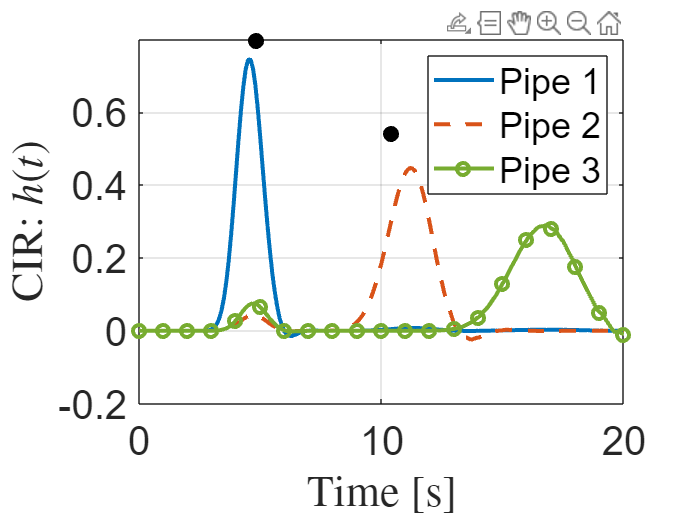


%Peclet number, see [3, Eq. below 11] 
Pe=v_char*height_pipe/D_coeff;

%Evaluating the Effective Diffusion coefficient
%Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
%Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
D_eff=D_coeff*(1+1/200*Pe^2);

%Matlab code to evaluate the integral
syms t x rd v varphi D C_0 w
% Define the substitution for x
z = (x - v*t + varphi*rd) / (2*sqrt(D*t));
% Define the integrand
integrand = 1/2*C_0*erfc(z);
% Perform the symbolic integration from r = 0 to r = dr
I = simplify(1/(w)*int(integrand, rd, 0, w));
%Performing the integral
c_avg=1/(w)*int(integrand,rd);
%evaluating the integral limits between rd=0 and rd=2r
c_avg_int=subs(c_avg,[rd,C_0],[w,1])-subs(c_avg,[rd,C_0],[0,1]);
c_avg_param_int_Pipe_3=subs(c_avg_int,[x,D,v,w,varphi],[L_3,D_eff,v_char,w_3,varphi_3]);
conc_Pipe_3_Theo=double(subs(c_avg_param_int_Pipe_3,[t],[time(2:end)]));

% %Evaluating the concentration of the straigth channel
% conc_Pipe_3_Theo=1./2.*erfc((L_3-v_char*time)./(2*sqrt(D_eff*time)));
% %Evaluating the channel impulse response
h_cir_3_Theo=gradient(conc_Pipe_3_Theo,time(2:end));

%finding the maximum
tau_3=L_3/v_char-2*D_eff/v_char^2;
[~,idx]=min(abs(time-tau_3));
peak_3=h_cir_3_Theo(idx);

figure;
p1=plot(time,h_cir_1_COMSOL,'-','LineWidth',2,'MarkerIndices',1:10:length(conc_Pipe_1_COMSOL));grid on; hold on;
plot(tau_1,peak_1,'o','LineWidth',2,'Color','black',MarkerFaceColor='black');
p2=plot(time,h_cir_2_COMSOL,'--','LineWidth',2,'MarkerIndices',1:10:length(conc_Pipe_1_COMSOL),'Color',"#D95319");
plot(tau_2,peak_2,'o','LineWidth',2,'Color','black',MarkerFaceColor='black');
p3=plot(time,h_cir_3_COMSOL,'-o','LineWidth',2,'MarkerIndices',1:10:length(conc_Pipe_1_COMSOL),'Color',"#77AC30");
plot(tau_3,peak_3,'o','LineWidth',2,'Color','black',MarkerFaceColor='black');
xlabel("Time [s]",'Interpreter','latex');
ylabel("CIR: $h(t)$",'Interpreter','latex');
set(gca,'FontSize',fontsize);
legend([p1,p2,p3],{'Pipe 1','Pipe 2','Pipe 3'},'Location','northeast');

### Phase 2

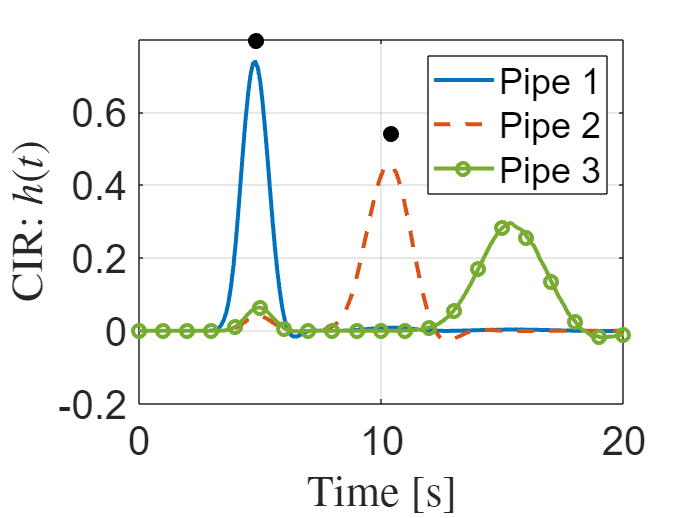

%Pipe 1
% Specify the MAT file for the parameters
csvFileName = '3D_Pipe_1_Outlet_Concentration_Surface_Average_Phase_2.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
table=readtable(csvFileName,opts);
time=table.Var1;
%concentration
conc_Pipe_1_COMSOL=table.Var2;
%CIR
h_cir_1_COMSOL=gradient(conc_Pipe_1_COMSOL,time);

%Pipe 2
% Specify the MAT file for the parameters
% csvFileName = 'COMSOL_pipe_1_concentration_line_outlet.csv';
csvFileName = '3D_Pipe_2_Outlet_Concentration_Surface_Average_Phase_2.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
table=readtable(csvFileName,opts);
time=table.Var1;
%concentration
conc_Pipe_2_COMSOL=table.Var2;
%CIR
h_cir_2_COMSOL=gradient(conc_Pipe_2_COMSOL,time);

%Pipe 3
% Specify the MAT file for the parameters
% csvFileName = 'COMSOL_pipe_1_concentration_line_outlet.csv';
csvFileName = '3D_Pipe_3_Outlet_Concentration_Surface_Average_Phase_2.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
table=readtable(csvFileName,opts);
time=table.Var1;
%concentration
conc_Pipe_3_COMSOL=table.Var2;
%CIR
h_cir_3_COMSOL=gradient(conc_Pipe_3_COMSOL,time);


figure;
p1=plot(time,h_cir_1_COMSOL,'-','LineWidth',2,'MarkerIndices',1:10:length(conc_Pipe_1_COMSOL));grid on; hold on;
plot(tau_1,peak_1,'o','LineWidth',2,'Color','black',MarkerFaceColor='black');
p2=plot(time,h_cir_2_COMSOL,'--','LineWidth',2,'MarkerIndices',1:10:length(conc_Pipe_1_COMSOL),'Color',"#D95319");
plot(tau_2,peak_2,'o','LineWidth',2,'Color','black',MarkerFaceColor='black');
p3=plot(time,h_cir_3_COMSOL,'-o','LineWidth',2,'MarkerIndices',1:10:length(conc_Pipe_1_COMSOL),'Color',"#77AC30");
plot(tau_3,peak_3,'o','LineWidth',2,'Color','black',MarkerFaceColor='black');
xlabel("Time [s]",'Interpreter','latex');
ylabel("CIR: $h(t)$",'Interpreter','latex');
set(gca,'FontSize',fontsize);
legend([p1,p2,p3],{'Pipe 1','Pipe 2','Pipe 3'},'Location','northeast');

#### For validation purposes

i_l=30;
i_w=1;
syms t
%Hydraulic Resistance
R=12*mu*l_vec(i_l)/(1-0.63*height_pipe/w_vec(i_w))*1/(height_pipe^3*w_vec(i_w));

%Volumetric flow
Q=p0/R;

%Mean velocity
%Circular channel of radius r_vec(i_r) [2, pag. 54]
% v_char=r_vec(i_r)^2*p0/(3*mu*l_vec(i_l))
%Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
v_char=Q/(w_vec(i_w)*height_pipe);

%Peclet number, see [3, Eq. below 11]
Pe=v_char*height_pipe/D_coeff;

%Evaluating the Effective Diffusion coefficient
%Circular channel: [1, Eq.(4.54) pp.77]
%D_eff=r_vec(i_w)^2*v_char^2/48/D_coeff;
%Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
%Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
D_eff=D_coeff*(1+1/200*Pe^2);

%Evaluating the concentration of the straigth channel
c=1./2.*erfc((l_vec(i_l)-v_char*t)./(2*sqrt(D_eff*t)));
%Evaluating the channel impulse response
h=diff(c,t);
h_vs_t=subs(h,t_vector);
%for validation purposes only


%defining the time interval
total_points_time=1e3;
t_ini=1e-7;
t_end=2;
t_vector = linspace(t_ini,t_end,total_points_time);
time_sampling=t_vector(2)-t_vector(1);

%finding the maximum
tau_1=l_vec(i_l)/v_char-2*D_eff/v_char^2;
[~,idx]=min(abs(t_vector-tau_1));
peak_1=h_vs_t(idx);

figure;
plot(t_vector,h_vs_t,'LineWidth',2); grid on; hold on;
plot(tau_1,peak_1,'o','LineWidth',2); grid on; hold on;

xlabel('Time [s]','Interpreter','latex');
ylabel ('$h_1(t)$','Interpreter','latex');
%axis([tau_1/10 4*tau_1 0 2])
set(gca,'FontSize',fontsize);

h_vs_t=subs(h,t_vector);
[h_amp(i_w,i_l),idx]=max(h_vs_t);
h_tau(i_w,i_l)=t_vector(idx);



% Plotting the surface for the peak_tau matrix
figure;
s=surf(l_vec*1e3, w_vec*1e6, h_tau);hold on
s.EdgeColor = 'none';
xlabel('Length [mm]','Interpreter','latex');
ylabel('Width [$\mu$m]','Interpreter','latex');
zlabel('Peak time $\tau$ [s]','Interpreter','latex');
title('Pipe 1')
%axis([l_vec(1)*1e3 l_vec*1e3 w_vec(1)*1e6 w_vec*1e6])
set(gca, 'YDir', 'normal');
set(gca,'FontSize',fontsize ,'YDir', 'normal'); % To display the y-axis in the correct direction

% Plotting the surface for the peak_tau matrix
figure;
s=surf(l_vec*1e3, w_vec*1e6, h_amp); hold on
s.EdgeColor = 'none';
xlabel('Length [mm]','Interpreter','latex');
ylabel('Width [$\mu$m]','Interpreter','latex');
zlabel('Peak amplitude','Interpreter','latex');
title('Pipe 1')
% axis([l_vec(1)*1e3 l_vec(col)*1e3 w_vec(1)*1e6 w_vec*1e6])
set(gca, 'YDir', 'normal');
set(gca,'FontSize',fontsize ,'YDir', 'normal'); % To display the y-axis in the correct direction
view(-40, 51); % Adjust the view angle for better visualization

% Superposing the tau_coords on the plot
plot3(l_vec(tau_coords(:,2))*1e3, w_vec(tau_coords(:,1))*1e6, tau_coords(:,4), 'o-',...
    'MarkerSize', 12, 'Color','#D95319','MarkerFaceColor','#D95319');
hold off;

#### Peak time and peak amplitude vs width and length

%Loading results
% Ensure the dataset folder exists
outputFolder = 'dataset';
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end

load(fullfile(outputFolder, 'tau_vs_r_l.mat'))


#### Synthesis of length and radius for a given tau_sample

% Given value of tau
tau_value = 3; % Replace 'tau' with the actual value if needed

% Finding the closest coordinates to tau, 2*tau, and 3*tau in the peak_tau matrix
tau_coords = zeros(3, 4); % Preallocate for coordinates

for k = 1:3
    target_value = k * tau_value;
    [row, col] = find(abs(peak_tau - target_value) == min(min(abs(peak_tau - target_value))));
    tau_coords(k, :) = [row, col, target_value, peak_amp(row,col)];
end

%find the coordinates where calculations are zero
[row, col] = find(peak_tau < peak_tau(end,1),1);
disp('Row coordinates where peak_tau is zero:');
disp(row);
disp('Column coordinates where peak_tau is zero:');
disp(col);


if isempty(col)
    [~,col]=size(peak_tau);
end

col=50
% Plotting the surface for the peak_tau matrix
figure;
s=surf(l_vec(1:col)*1e3, w_vec(1:col)*1e6, peak_tau(1:col,1:col));hold on
s.EdgeColor = 'none';
xlabel('Length [mm]','Interpreter','latex');
ylabel('Width [$\mu$m]','Interpreter','latex');
zlabel('Peak time $\tau$ [s]','Interpreter','latex');
axis([l_vec(1)*1e3 l_vec(col)*1e3 w_vec(1)*1e6 w_vec(col)*1e6])
set(gca, 'YDir', 'normal');
set(gca,'FontSize',fontsize ,'YDir', 'normal'); % To display the y-axis in the correct direction

view(-40, 51); % Adjust the view angle for better visualization

% Superposing the tau_coords on the plot
plot3(l_vec(tau_coords(:,2))*1e3, w_vec(tau_coords(:,1))*1e6, tau_coords(:,3), 'o-',...
    'MarkerSize', 12, 'Color','#D95319','MarkerFaceColor','#D95319');
hold off;

% Plotting the surface for the peak_tau matrix
figure;
s=surf(l_vec(1:col)*1e3, w_vec(1:col)*1e6, peak_amp(1:col,1:col)); hold on
s.EdgeColor = 'none';
xlabel('Length [mm]','Interpreter','latex');
ylabel('Width [$\mu$m]','Interpreter','latex');
zlabel('Peak amplitude','Interpreter','latex');
axis([l_vec(1)*1e3 l_vec(col)*1e3 w_vec(1)*1e6 w_vec(col)*1e6])
set(gca, 'YDir', 'normal');
set(gca,'FontSize',fontsize ,'YDir', 'normal'); % To display the y-axis in the correct direction
view(-40, 51); % Adjust the view angle for better visualization

% Superposing the tau_coords on the plot
plot3(l_vec(tau_coords(:,2))*1e3, w_vec(tau_coords(:,1))*1e6, tau_coords(:,4), 'o-',...
    'MarkerSize', 12, 'Color','#D95319','MarkerFaceColor','#D95319');
hold off;

% Finding the derivative of the peak_tau matrix with respect to the length and radius
[rows, cols] = size(peak_tau);
peak_tau_derivative = zeros(rows, cols);

for i = 1:col
    for j = 1:col
        if i > 1
            dL = l_vec(i) - l_vec(i-1);
            peak_tau_derivative(i, j) = (peak_tau(i, j) - peak_tau(i-1, j)) / dL;
        end
        if j > 1
            dR = r_vec(j) - r_vec(j-1);
            peak_tau_derivative(i, j) = (peak_tau(i, j) - peak_tau(i, j-1)) / dR;
        end
    end
end

% % Displaying the derivative matrix
% disp('Derivative of peak_tau matrix:');
% disp(peak_tau_derivative);

% Plotting the derivative of the peak_tau matrix
figure;
s = surf(l_vec(2:col)*1e3, r_vec(2:col)*1e3, peak_tau_derivative(2:col, 2:col)); hold on;
s.EdgeColor = 'none';
xlabel('Length [mm]','Interpreter','latex');
ylabel('Radius [mm]','Interpreter','latex');
zlabel('$\tau''$','Interpreter','latex');
axis([l_vec(1)*1e3 l_vec(col)*1e3 r_vec(1)*1e3 r_vec(col)*1e3])
set(gca, 'YDir', 'normal');
set(gca,'FontSize',fontsize ,'YDir', 'normal'); % To display the y-axis in the correct direction
view(-40, 51); % Adjust the view angle for better visualization
hold on;


### Results for Pipe 1

%Loading results
% Ensure the dataset folder exists
outputFolder = 'dataset';
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end

load(fullfile(outputFolder, 'pipe_1_w_vs_l.mat'))

idx=find(w_vs_l_pipe_1~=0);
figure;
plot(l_vec(idx)*1e3,w_vs_l_pipe_1(idx)*1e6,'LineWidth',2); grid on;
xlabel('Length pipe 1 ($L_1$) [mm]','Interpreter','latex');
ylabel ('Radius pipe 1 ($r_1$) $\mu$m]','Interpreter','latex');
set(gca,'FontSize',fontsize);

syms t
%Validation of time and peak amplitude sampling
peak_amp_pipe_1=zeros(1,length(idx));

% figure;

for i=1:length(idx)
    L_1=l_vec(idx(i));
    w_1=w_vs_l_pipe_1(idx(i));

    %Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
    v_char=Q_m3_s/(w_1*height_pipe);

    %Peclet number, see [3, Eq. below 11] 
    Pe=v_char*height_pipe/D_coeff;

    %Evaluating the Effective Diffusion coefficient
    %Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
    %Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
    D_eff=D_coeff*(1+1/200*Pe^2);

    %Evaluating the concentration of the straigth channel
    c=1./2.*erfc((L_1-v_char*t)./(2*sqrt(D_eff*t)));
    %Evaluating the channel impulse response
    h=diff(c,t);
    % for validation purposes only
    % fplot(h,[tau_1/10 3*tau_1]); grid on; hold on;

    %
    peak_amp_pipe_1(i)=subs(h,t,tau_1);
end

% xlabel('Time [s]','Interpreter','latex');
% ylabel ('Straigth pipe 1 $h_1(t)$','Interpreter','latex');
% set(gca,'FontSize',fontsize);

figure;
%% colecting the amplitude
plot(l_vec(idx)*1e3,peak_amp_pipe_1,'LineWidth',2);grid on;
xlabel('Length pipe 1 ($L_1$) [mm]','Interpreter','latex');
ylabel ('max $h_1(t)$','Interpreter','latex');
set(gca,'FontSize',fontsize);

### Plotting $h_1(t)$

figure;

target_1=50*1e-3;
target_2=100*1e-3;
target_3=150*1e-3;

[~, idx_1] = min(abs(l_vec(idx) - target_1));  % idx is index of closest value
[~, idx_2] = min(abs(l_vec(idx) - target_2));  % idx is index of closest value
[~, idx_3] = min(abs(l_vec(idx) - target_3));  % idx is index of closest value


samples=[idx_1,idx_2,idx_3];

legend_text=cell(1,length(samples));
m=1; %index for the legend
for i=samples
    L_1=l_vec(idx(i));
    w_1=w_vs_l_pipe_1(idx(i));

    %mean velocity
    %Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
    v_char=Q_m3_s/(w_1*height_pipe);

    %Peclet number, see [3, Eq. below 11] 
    Pe=v_char*height_pipe/D_coeff;

    %Evaluating the Effective Diffusion coefficient
    %Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
    %Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
    D_eff=D_coeff*(1+1/200*Pe^2);

    %Evaluating the concentration of the straigth channel
    c=1./2.*erfc((L_1-v_char*t)./(2*sqrt(D_eff*t)));
    % Evaluating the channel impulse response
    h=diff(c,t);

    fplot(h,[tau_1/10 4*tau_1],'LineWidth',2); grid on; hold on;

    %legend on the plot
    legend_text{m}=strcat('$r_1=',num2str(w_1*1e6,3),'$ [$\mu$m] $L_1=',num2str(L_1*1e3,3),'$ [mm]');
    m=m+1;
    
end

legend({legend_text{:}},...
    'Location','northwest','NumColumns',1,'Interpreter',"latex",'FontSize',fontsize);%

xlabel('Time [s]','Interpreter','latex');
ylabel ('$h_1(t)$','Interpreter','latex');
axis([tau_1/10 4*tau_1 0 2])
set(gca,'FontSize',fontsize);


#### Evaluating the approximate time to fill in the reader

%Evaluating the reader volume and time to fill the volume
r_Reader=500e-6/2;
r_pipe=51.2e-6;%solution from the h1(t) plot
l_pipe=51.3e-3;%solution from the h1(t) plot

reader_delay=2*pi*r_Reader^2*r_pipe/Q_m3_s

%Evaluating the CNN delay
v_char=r_pipe^2*p0/(3*mu*l_pipe);
%CNN_delay=l_pipe/v_char

reader_delay/tau_sample*100

### Results Pipe 2

%Loading results
% Ensure the dataset folder exists
outputFolder = 'dataset';
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end

load(fullfile(outputFolder, 'pipe_2_w_vs_varphi.mat'))

idx=find(w_vs_varphi_pipe_2~=0);

figure;
plot(varphi_vec(idx),w_vs_varphi_pipe_2(idx)*1e6,'LineWidth',2); grid on;
xlabel('Turning angle ($\varphi$) [rad]','Interpreter','latex');
ylabel ('Radius pipe 2 ($r_2$) [$\mu$m]','Interpreter','latex');
set(gca,'FontSize',fontsize);

%Validation
%Evaluating the channel impulse response
%Matlab code to evaluate the integral
syms t x w rd v varphi D C_0
% Define the substitution for x
z = (x - v*t + varphi*rd) / (2*sqrt(D*t));
% Define the integrand
integrand = 1/2*C_0*erfc(z);
% Perform the symbolic integration from r = 0 to r = dr
I = simplify(1/(w)*int(integrand, rd, 0, w));
%Performing the integral
c_avg=1/(w)*int(integrand,rd);
%evaluating the integral limits between rd=0 and rd=2r
c_avg_int=subs(c_avg,[rd,C_0],[w,1])-subs(c_avg,[rd,C_0],[0,1]);

peak_amp_pipe_2=zeros(1,length(idx));
for i=1:length(idx)
    L_2=L_1/sin((pi-varphi)/2);

    %Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
    v_char=Q_m3_s/(w*height_pipe);

    %Peclet number, see [3, Eq. below 11] 
    Pe=v_char*height_pipe/D_coeff;

    %Evaluating the Effective Diffusion coefficient
    %Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
    %Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
    D_eff=D_coeff*(1+1/200*Pe^2);

    c_avg_param_int=subs(c_avg_int,[x,D,v],[L_2,D_eff,v_char]);

    %evaluating the channel impulse response
    h_turn=diff(c_avg_param_int,t);
    peak_amp_pipe_2(i)=subs(h_turn,[t,w,varphi],[2*tau_1,w_vs_varphi_pipe_2(idx(i)),varphi_vec(idx(i))]);
end

xlabel('Time [s]','Interpreter','latex');
ylabel ('Radius pipe 2 ($r_2$)','Interpreter','latex');
set(gca,'FontSize',fontsize);

figure;
%% colecting the amplitude
plot(subs(L_1/sin((pi-varphi)/2),varphi,varphi_vec(idx))*1e3,peak_amp_pipe_2,'LineWidth',2);grid on;
xlabel('Length pipe 2 ($L_2$) [mm]','Interpreter','latex');
ylabel ('max $h_2(t)$','Interpreter','latex');
set(gca,'FontSize',fontsize);


### Plotting $h_2(t)$

%Validation
%Evaluating the channel impulse response
%Matlab code to evaluate the integral
syms t x w rd v varphi D C_0
% Define the substitution for x
z = (x - v*t + varphi*rd) / (2*sqrt(D*t));
% Define the integrand
integrand = 1/2*C_0*erfc(z);
% Perform the symbolic integration from r = 0 to r = dr
I = simplify(1/(w)*int(integrand, rd, 0, w));
%Performing the integral
c_avg=1/(w)*int(integrand,rd);
%evaluating the integral limits between rd=0 and rd=2r
c_avg_int=subs(c_avg,[rd,C_0],[w,1])-subs(c_avg,[rd,C_0],[0,1]);

samples=[1,round(length(idx)/2),length(idx)];
legend_text=cell(1,length(samples));
m=1;
figure;
peak_amp_pipe_2=zeros(1,length(idx));
for i=samples
    L_2=L_1/sin((pi-varphi)/2);

    %Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
    v_char=Q_m3_s/(w*height_pipe);

    %Peclet number, see [3, Eq. below 11] 
    Pe=v_char*height_pipe/D_coeff;

    %Evaluating the Effective Diffusion coefficient
    %Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
    %Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
    D_eff=D_coeff*(1+1/200*Pe^2);

    c_avg_param_int=subs(c_avg_int,[x,D,v],[L_2,D_eff,v_char]);

    %evaluating the channel impulse response
    h_turn=diff(c_avg_param_int,t);
    w_2=w_vs_varphi_pipe_2(idx(i));
    L_2_val=double(subs(L_2,varphi,varphi_vec(idx(i))));
    fplot(subs(h_turn,[w,varphi],[w_2,varphi_vec(idx(i))]),[tau_1/10 4*tau_1],'LineWidth',2); grid on; hold on;
    
    %legend on the plot
    legend_text{m}=strcat('$w_2=',num2str(w_2*1e6,3),'$ [$\mu$m] $L_2=',num2str(L_2_val*1e3,3),'$ [mm]');
    m=m+1;
    
end

legend({legend_text{:}},...
    'Location','northwest','NumColumns',1,'Interpreter',"latex",'FontSize',fontsize);%

axis([tau_1/10 4*tau_1 0 2])

xlabel('Time [s]','Interpreter','latex');
ylabel ('$h_2(t)$','Interpreter','latex');
set(gca,'FontSize',fontsize);

### Results Pipe 3

%Loading results
% Ensure the dataset folder exists
outputFolder = 'dataset';
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end

load(fullfile(outputFolder, 'pipe_3_w_vs_varphi.mat'))

idx=find(w_vs_varphi_pipe_3~=0);

figure;
plot(varphi_vec(idx),w_vs_varphi_pipe_3(idx)*1e6,'LineWidth',2); grid on;
xlabel('Turning angle ($\varphi$) [rad]','Interpreter','latex');
ylabel ('Turning pipe radius $\mu$m]','Interpreter','latex');
set(gca,'FontSize',fontsize);

%Validation
%Evaluating the channel impulse response
%Matlab code to evaluate the integral
syms t x w rd v varphi D C_0
% Define the substitution for x
z = (x - v*t + varphi*rd) / (2*sqrt(D*t));
% Define the integrand
integrand = 1/2*C_0*erfc(z);
% Perform the symbolic integration from r = 0 to r = dr
I = simplify(1/(w)*int(integrand, rd, 0, w));
%Performing the integral
c_avg=1/(w)*int(integrand,rd);
%evaluating the integral limits between rd=0 and rd=2r
c_avg_int=subs(c_avg,[rd,C_0],[w,1])-subs(c_avg,[rd,C_0],[0,1]);

% figure;
peak_amp_pipe_3=zeros(1,length(idx));
for i=1:length(idx)
    L_3=L_1/sin((pi-varphi)/2);

    %Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
    v_char=Q_m3_s/(w*height_pipe);

    %Peclet number, see [3, Eq. below 11] 
    Pe=v_char*height_pipe/D_coeff;

    %Evaluating the Effective Diffusion coefficient
    %Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
    %Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
    D_eff=D_coeff*(1+1/200*Pe^2);

    c_avg_param_int=subs(c_avg_int,[x,D,v],[L_3,D_eff,v_char]);

    %evaluating the channel impulse response
    h_turn=diff(c_avg_param_int,t);
    % fplot(subs(h_turn,[r,varphi],[w_vs_varphi_pipe_2(idx(i)),varphi_vec(idx(i))]),[tau_1/10 3*tau_1]); grid on; hold on;

    peak_amp_pipe_3(i)=subs(h_turn,[t,w,varphi],[3*tau_1,w_vs_varphi_pipe_3(idx(i)),varphi_vec(idx(i))]);
end


figure;
%% colecting the amplitude
plot(subs(L_1/sin((pi-varphi)/2),varphi,varphi_vec(idx))*1e3,peak_amp_pipe_3,'LineWidth',2);grid on;
xlabel('Straight pipe 3 length ($L_3$) [mm]','Interpreter','latex');
ylabel ('max $h_3(t)$','Interpreter','latex');
set(gca,'FontSize',fontsize);

### Plotting $h_3(t)$

%Validation
%Evaluating the channel impulse response
%Matlab code to evaluate the integral
syms t x w rd v varphi D C_0
% Define the substitution for x
z = (x - v*t + varphi*rd) / (2*sqrt(D*t));
% Define the integrand
integrand = 1/2*C_0*erfc(z);
% Perform the symbolic integration from r = 0 to r = dr
I = simplify(1/(w)*int(integrand, rd, 0, w));
%Performing the integral
c_avg=1/(w)*int(integrand,rd);
%evaluating the integral limits between rd=0 and rd=2r
c_avg_int=subs(c_avg,[rd,C_0],[w,1])-subs(c_avg,[rd,C_0],[0,1]);

samples=[1,round(length(idx)/2),length(idx)];
legend_text=cell(1,length(samples));
m=1;
figure;
peak_amp_pipe_2=zeros(1,length(idx));
for i=samples
    L_3=L_1/sin((pi-varphi)/2);

    %Rectangular channel of size w x h [1, below Eq. (3.40) pag. 53]
    v_char=Q_m3_s/(w*height_pipe);

    %Peclet number, see [3, Eq. below 11] 
    Pe=v_char*height_pipe/D_coeff;

    %Evaluating the Effective Diffusion coefficient
    %Shallow rectangular channel, h<<w, see the constant 1/200 in [3,
    %Eq. (15)] and the formula for the diffusion coeff in [3, Eq. (1)].
    D_eff=D_coeff*(1+1/200*Pe^2);

    c_avg_param_int=subs(c_avg_int,[x,D,v],[L_3,D_eff,v_char]);

    %evaluating the channel impulse response
    h_turn=diff(c_avg_param_int,t);
    w_3=w_vs_varphi_pipe_3(idx(i));
    L_3_val=double(subs(L_3,varphi,varphi_vec(idx(i))));
    fplot(subs(h_turn,[w,varphi],[w_3,varphi_vec(idx(i))]),[tau_1/10 4*tau_1],'LineWidth',2); grid on; hold on;
    
    %legend on the plot
    legend_text{m}=strcat('$w_3=',num2str(w_3*1e6,3),'$ [$\mu$m] $L_3=',num2str(L_3_val*1e3,3),'$ [mm]');
    m=m+1;
    
end

legend({legend_text{:}},...
    'Location','northwest','NumColumns',1,'Interpreter',"latex",'FontSize',fontsize);%

axis([tau_1/10 4*tau_1 0 2])

xlabel('Time [s]','Interpreter','latex');
ylabel ('$h_3(t)$','Interpreter','latex');
set(gca,'FontSize',fontsize);

#### Peak time and peak amplitude vs radius and length

% operating on the permisible range
total_points=20;
r_vec=linspace(50,60,total_points)*1e-6;%radius cilinder
l_vec=linspace(12,100,total_points)*1e-3;%length of the pipe

%defining the time interval
total_points=1e3;
time_ini=1e-7;
time_end=300;
time_vector = linspace(time_ini,time_end,total_points);

syms t

peak_amp=zeros(length(r_vec),length(l_vec));
peak_tau=zeros(length(r_vec),length(l_vec));

for i_w=1:length(r_vec)

    i_w/length(r_vec)*100

    for i_l=1:length(l_vec)

        %Evaluating the mean velocity [2, pag. 54]
        v_char=r_vec(i_w)^2*p0/(3*mu*l_vec(i_l));

        %Evaluating the Effective Diffusion
        %[1, Eq.(4.54) pp.77]
        D_eff=r_vec(i_w)^2*v_char^2/48/D_coeff;

        %Validating the diffusion within the pipe
        %Evaluation of the Péclet number, this evaluation follows [1,Eq. (4.44) pp.75]
        Pe=r_vec(i_w)*v_char/D_coeff;

        if(Pe>4*l_vec(i_l)/r_vec(i_w))            
            disp(['Concentration is not constant along the x-axis, Pe=',num2str(Pe),' is larger than ',num2str(4*l_vec(i_l)/r_vec(i_w))])
            i_l
            i_w
        end

        if(Pe<sqrt(48))            
            disp(['Diffusion hasn''t occurred along the axis, Pe=',num2str(Pe),' is less than ',num2str(sqrt(48))])
            i_l
            i_w
        end

        %Evaluating the concentration of the straigth channel
        c=1./2.*erfc((l_vec(i_l)-v_char*t)./(2*sqrt(D_eff*t)));
        %Evaluating the channel impulse response
        h=diff(c,t);

        % %for testing purposes only
        % figure;plot(time_vector,subs(h,time_vector)); grid on;

        %Looking for the maximum of the channel impulse response with the first derivative
        h_diff=diff(h,t);
        %Evaluating the derivative with time
        obj_fcn_time=double(subs(h_diff, t, time_vector));

        % %for testing purposes
        % figure;plot(time_vector,obj_fcn_time);

        %Evaluating the time interval where the first derivative is zero
        [~, max_time] = max(obj_fcn_time);
        [~, min_time] = min(obj_fcn_time);
        
        % %for testing purposes
        % time_vector(max_time)
        % time_vector(min_time)
        
        %looking for the peak time and peak amplitude
        peak_tau(i_w,i_l)=vpasolve(h_diff,t,[time_vector(max_time),time_vector(min_time)]);
        peak_amp(i_w,i_l)=subs(h, t, peak_tau(i_w,i_l));
    end
end

%Saving results
% Ensure the dataset folder exists
outputFolder = 'dataset';
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end

% Save the results into the specified folder
save(fullfile(outputFolder, 'tau_vs_r_l.mat') ,'peak_tau','peak_amp','p0','mu', 'time_vector','l_vec','r_vec');

% %Loading results
% % Ensure the dataset folder exists
% outputFolder = 'dataset';
% if ~exist(outputFolder, 'dir')
%     mkdir(outputFolder);
% end
% 
% load(fullfile(outputFolder, 'tau_vs_r_l.mat'))

% Plotting the surface for the peak_tau matrix
figure;
s=surf(l_vec*1e3, r_vec*1e6, peak_tau);
s.EdgeColor = 'none';
xlabel('Length [mm]','Interpreter','latex');
ylabel('Radius [$\mu$m]','Interpreter','latex');
zlabel('Peak time $\tau$ [s]','Interpreter','latex');
axis([l_vec(1)*1e3 l_vec(end)*1e3 r_vec(1)*1e6 r_vec(end)*1e6])
set(gca, 'YDir', 'normal');
set(gca,'FontSize',fontsize ,'YDir', 'normal'); % To display the y-axis in the correct direction
hold off;

view(-40, 51); % Adjust the view angle for better visualization

% Plotting the surface for the peak_tau matrix
figure;
s=surf(l_vec*1e3, r_vec*1e6, peak_amp);
s.EdgeColor = 'none';
xlabel('Length [mm]','Interpreter','latex');
ylabel('Radius [$\mu$m]','Interpreter','latex');
zlabel('Peak amplitude','Interpreter','latex');
axis([l_vec(1)*1e3 l_vec(end)*1e3 r_vec(1)*1e6 r_vec(end)*1e6])
set(gca, 'YDir', 'normal');
set(gca,'FontSize',fontsize ,'YDir', 'normal'); % To display the y-axis in the correct direction
hold off;
view(-40, 51); % Adjust the view angle for better visualization

function addingPathParentFolderByName(targetName)
    % Start from the current directory
    currFolder = pwd;
    found = false;
    
    % Continue searching until you reach the root folder
    while true
        % Get the parent folder
        [parentFolder, currentName] = fileparts(currFolder);
        
        % Check if the current folder's name is the target
        if strcmpi(currentName, targetName)
            found = true;
            break;
        end
        
        % If we've reached the root or no change, exit the loop
        if isempty(parentFolder) || strcmp(currFolder, parentFolder)
            break;
        end
        
        % Move one level up
        currFolder = parentFolder;
    end

    if found
        addpath(genpath(currFolder));
        fprintf('Adding matlab path to: %s\n', currFolder);
    else
        error('Folder named "%s" not found in any parent directory.', targetName);
    end
end

function [value,factor]= getVarTable(var,table)
%This function extract the value of the variable specified in the entry var within
%the table specified in entry table

varName = inputname(1);

%find the corresponding entry within the table of parameters
for i=1:numel(table(:,1))
    entry_str=strcmp(table{i,1},varName);
    if entry_str
        entry_table=i;
        break
    end
end

%validating
if isempty(entry_table)
    error('Table has no column named "%s".', varName);
    value=NaN;
    factor=NaN;
else
    %reading the value in the second column of the table
    str=table{entry_table,2};
    if(isempty(findstr(str{1},'[')))
        value=table{entry_table,2};
    else
        value=extractBefore(table{entry_table,2},'[');
    end
    %reading the units of the value within the second column in the table
    unit = extractBetween(table{entry_table,2}, "[", "]"); % e.g. ["um"; "mm"; "nm"; "m"]
    if isempty(unit)
        factor=1;
    else
        %Define your conversion map to meters
        convMap = containers.Map( ...
            {'nm','um','mm','cm','m','km','rad','s','ms','us','ns','Pa','mmHg','m/s','mol/m^3','mol/L','m^2/s','cm^2/s','g/mol'}, ...
            [1e-9,1e-6,1e-3,1e-2,1,1e3,1,1,1e-3,1e-6,1e-9,1,133.322,1,1,1e3,1,1e-4,1e-3] );
        %Finding the conversion factors
        if isKey(convMap, unit)
            factor = convMap(unit{1});
        else
            error('Unit "%s" not recognized.', unit{1});
        end
    end

end
end

function varName = getVarName(var)
%This function extract the value of the variable specified in var within
%the table specified in table

% getVarName   Extract the name of the workspace variable
varName = inputname(1);
end


## References

[1] H. Bruus, *Theoretical Microfluidics*. 2008. doi: [10.1093/oso/9780199235087.001.0001](https://doi.org/10.1093/oso/9780199235087.001.0001).  

[2] Howard C. Berg. 1993. Random Walks in Biology. Princeton University Press.

[3] M. L. Parks and L. A. Romero, “Taylor–Aris dispersion in high aspect ratio columns of nearly rectangular cross section,” *Mathematical and Computer Modelling*, vol. 46, no. 5, pp. 699–717, Sep. 2007, doi: [10.1016/j.mcm.2006.11.029](https://doi.org/10.1016/j.mcm.2006.11.029).  